cd /Users/serg/github_projects/QASS_SVM/data
load iris.mat
blackColor = [0 0 0];
rng('default')
rng(1234)

X = 6.* rand (100 , 3) - 3;
Y = sinc ( X (: ,1) ) + 0.1.* randn (100 ,1) ;

% priors 
gam = 20;
sig2 = 0.7;

[~ , alpha , b ] = bay_optimize ({ X , Y , 'f', gam , sig2 } , 1)

A =          -2.29363509138831
          3.63253851456189
          4.76454335996377
         -3.23325169430073
          4.68413318335027
          -5.8102869728559
         -1.58895322309336
          3.88763533397957
        -0.058881983362628
          1.16153013580945


alpha =          -2.29363509138831
          3.63253851456189
          4.76454335996377
         -3.23325169430073
          4.68413318335027
          -5.8102869728559
         -1.58895322309336
          3.88763533397957
        -0.058881983362628
          1.16153013580945


b =        -0.0427075667898418


[~ , gam ] = bay_optimize ({ X , Y , 'f', gam , sig2 } , 2) 

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


gam =           7.93571508498627


[~ , sig2 ] = bay_optimize ({ X , Y , 'f', gam , sig2 } , 3)

 
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
sig2 = 0.7 costL3 = -15.0154;
 

Local minimu

sig2 =         -0.240556647629862


gam

gam =           7.93571508498627


sig2

sig2 =         -0.240556647629862


[selected, ranking] = bay_lssvmARD({X, Y, 'f', gam, sig2});

ans = 'OPTIMIZING GAMMA AND KERNEL PARAMETERS WITH BAYESIAN FRAMEWORK OVER ALL INPUTS...'

 
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
sig2 = 3 costL3 = 27.4046;
 

Local minimum p

ans = 'testing for 3 inputs'

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping c

ans = 'SELECTED INPUT(S) ('discrete'): [1  3]'

ans = 'testing for 2 inputs'

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


ans = 'SELECTED INPUT(S) ('discrete'): [1]'


figure;
plotlssvm({X(:,1),Y,'f',gam, sig2,'RBF_kernel','preprocess'}); 

Start Plotting...finished


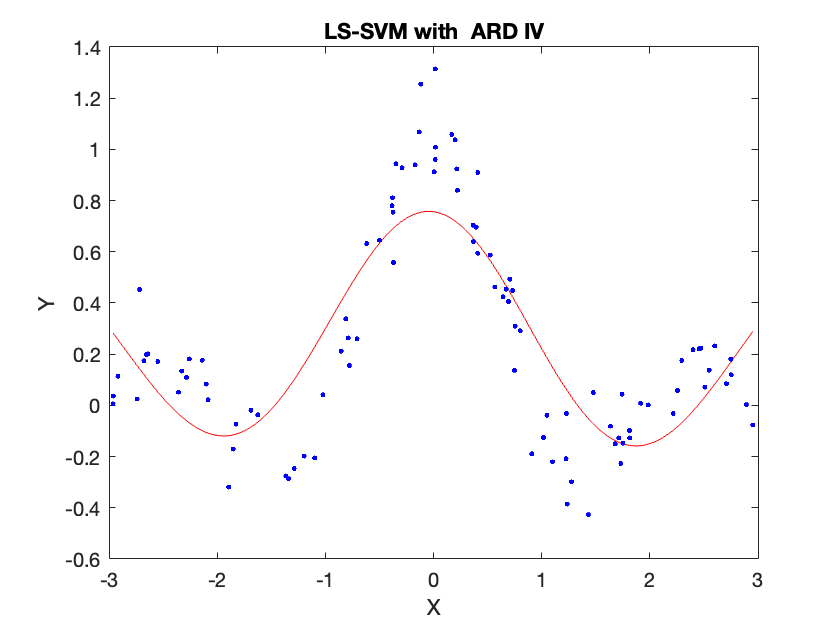

title('LS-SVM with  ARD IV')
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_213_2.png','Resolution',300)



figure;
plotlssvm({X(:,2),Y,'f',gam, sig2,'RBF_kernel','preprocess'});

Start Plotting...finished


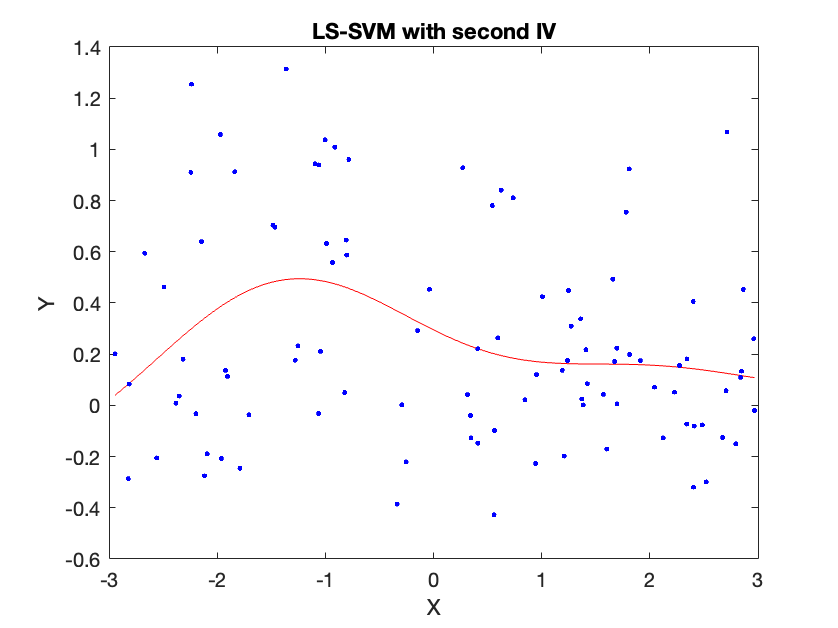

title('LS-SVM with second IV')
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_213_3.png','Resolution',300)


figure;
plotlssvm({X(:,3),Y,'f',gam, sig2,'RBF_kernel','preprocess'});

Start Plotting...finished


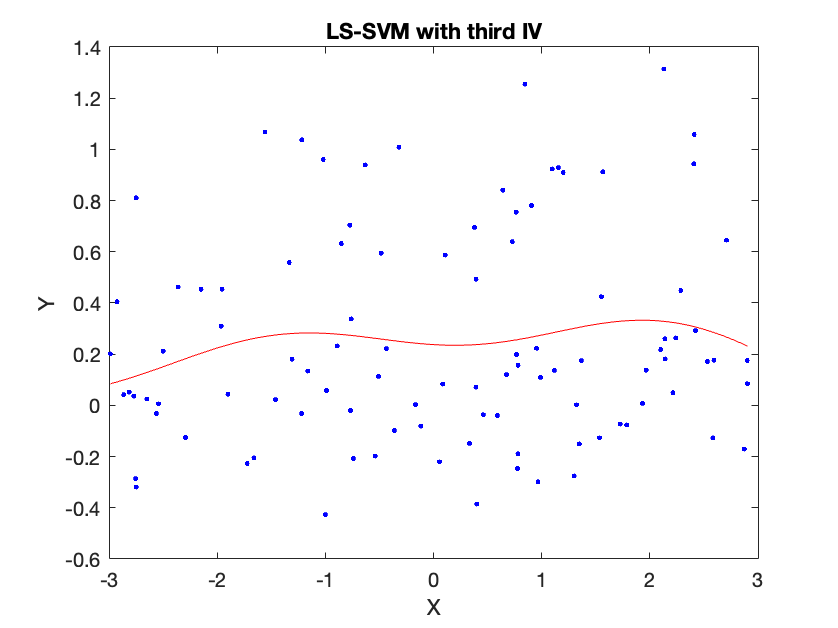

title('LS-SVM with third IV')
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_213_4.png','Resolution',300)